# SIFT

Avant de pouvoir lancer ce programme, il faut lancer la fonction suivante dans un fichier vl_setup.m séparé :

%  function path = vl_setup(varargin)
% % VL_SETUP Add VLFeat Toolbox to the path
% %   PATH = VL_SETUP() adds the VLFeat Toolbox to MATLAB path and
% %   returns the path PATH to the VLFeat package.
% %
% %   VL_SETUP('NOPREFIX') adds aliases to each function that do not
% %   contain the VL_ prefix. For example, with this option it is
% %   possible to use SIFT() instead of VL_SIFT().
% %
% %   VL_SETUP('TEST') or VL_SETUP('XTEST') adds VLFeat unit test
% %   function suite. See also VL_TEST().
% %
% %   VL_SETUP('QUIET') does not print the greeting message.
% %
% %   See also: VL_ROOT(), VL_HELP().
% 
% % Authors: Andrea Vedaldi and Brian Fulkerson
% 
% % Copyright (C) 2007-12 Andrea Vedaldi and Brian Fulkerson.
% % All rights reserved.
% %
% % This file is part of the VLFeat library and is made available under
% % the terms of the BSD license (see the COPYING file).
% 
% noprefix = false ;
% quiet = true ;
% xtest = false ;
% demo = false ;
% 
% for ai=1:length(varargin)
%   opt = varargin{ai} ;
%   switch lower(opt)
%     case {'noprefix', 'usingvl'}
%       noprefix = true ;
%     case {'test', 'xtest'}
%       xtest = true ;
%     case {'demo'}
%       demo = true ;
%     case {'quiet'}
%       quiet = true ;
%     case {'verbose'}
%       quiet = false ;
%     otherwise
%       error('Unknown option ''%s''.', opt) ;
%   end
% end
% 
% % Do not use vl_root() to avoid conflicts with other VLFeat
% % installations.
% 
% [a,b,c] = fileparts(mfilename('fullpath')) ;
% [a,b,c] = fileparts(a) ;
% root = a ;
% 
% addpath(fullfile(root,'toolbox'             )) ;
% addpath(fullfile(root,'toolbox','aib'       )) ;
% addpath(fullfile(root,'toolbox','geometry'  )) ;
% addpath(fullfile(root,'toolbox','imop'      )) ;
% addpath(fullfile(root,'toolbox','kmeans'    )) ;
% addpath(fullfile(root,'toolbox','misc'      )) ;
% addpath(fullfile(root,'toolbox','mser'      )) ;
% addpath(fullfile(root,'toolbox','plotop'    )) ;
% addpath(fullfile(root,'toolbox','quickshift')) ;
% addpath(fullfile(root,'toolbox','sift'      )) ;
% addpath(fullfile(root,'toolbox','special'   )) ;
% addpath(fullfile(root,'toolbox','slic'      )) ;
% addpath(fullfile(root,'toolbox','gmm'       )) ;
% addpath(fullfile(root,'toolbox','vlad'      )) ;
% addpath(fullfile(root,'toolbox','fisher'    )) ;
% 
% if vl_isoctave()
%   addpath(genpath(fullfile(root,'toolbox','mex','octave'))) ;
%   warning('off', 'Octave:possible-matlab-short-circuit-operator') ;
%   pkg load image ;
% else
%   bindir = mexext ;
%   if strcmp(bindir, 'dll'), bindir = 'mexw32' ; end
%   addpath(fullfile(root,'toolbox','mex',bindir)) ;
% end
% 
% if noprefix
%   addpath(fullfile(root,'toolbox','noprefix')) ;
% end
% 
% if xtest
%   addpath(fullfile(root,'toolbox','xtest')) ;
% end
% 
% if demo
%   addpath(fullfile(root,'toolbox','demo')) ;
% end
% 
% if ~quiet
%   if exist('vl_version') == 3
%     fprintf('VLFeat %s ready.\n', vl_version) ;
%   else
%     warning('VLFeat does not seem to be installed correctly. Make sure that the MEX files are compiled.') ;
%   end
% end
% 
% if nargout == 0
%   clear path ;
% end

### Barrieres

Nous allons tester SIFT sur une image de barrières de barbelés.

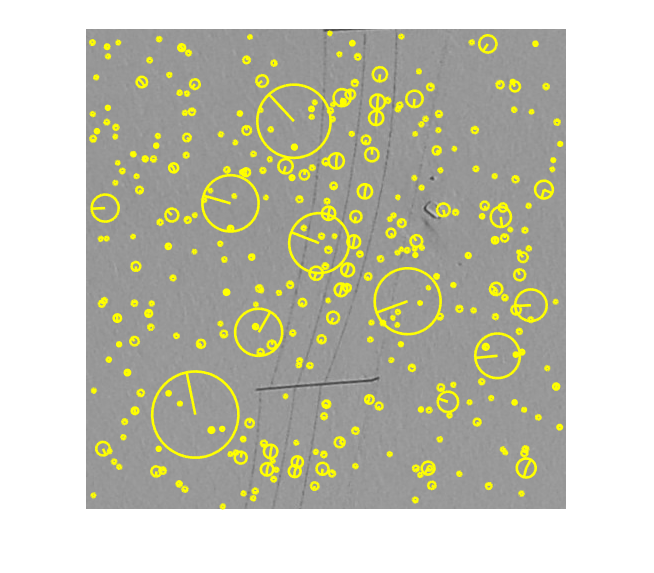

I = imread("Selection_imagettes\Barrière\40_44.png");
I = single(rgb2gray(I)) ;

edge_thresh = 10;
peak_thresh = 0;
edgePoints= vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;
figure,imshow(I/255) ;
h2 = vl_plotframe(edgePoints) ;
set(h2,'color','y','linewidth',2) ;

Il ne semble pas y avoir de schéma spécifique dans la distribution des points saillants à l'exception d'une ligne de points entre deux fils de barblés.

La majorité des points trouvés sont des faux positifs.

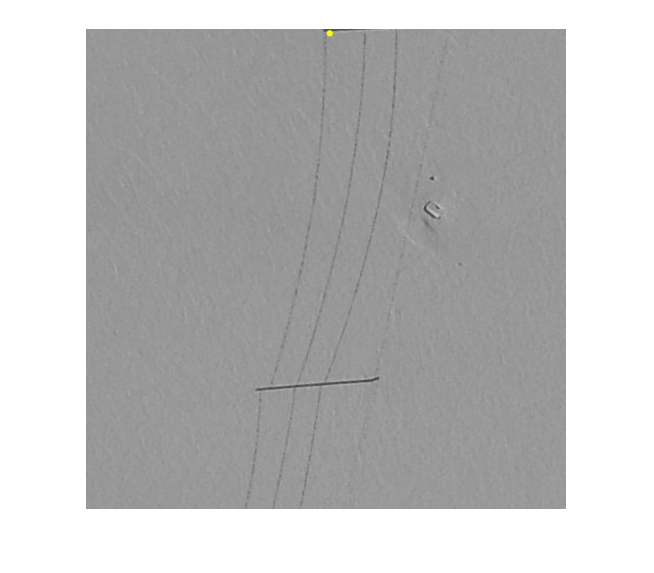

edge_thresh = 10;
peak_thresh = 2;
edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;
figure,imshow(I/255) ;
h2 = vl_plotframe(edgePoints) ;
set(h2,'color','y','linewidth',2) ;

En optimisant les paramètres, on essaye d'éliminer les faux positifs. Le résultat n'est pas meilleur. Cette image est le meilleur cas possible pour la détection de barbelés, le fond est très uniforme et l'ombre barrière se distingue bien à l'oeil nu.

D'après ces résultats et après des tests de paramétrage sur cette image et d'autres images de barbelés nous avons abandonné la méthode SIFT pour la détection de barrières de barbelés.

### Carcasses

Nous allons tester SIFT sur une image de Carcasse.

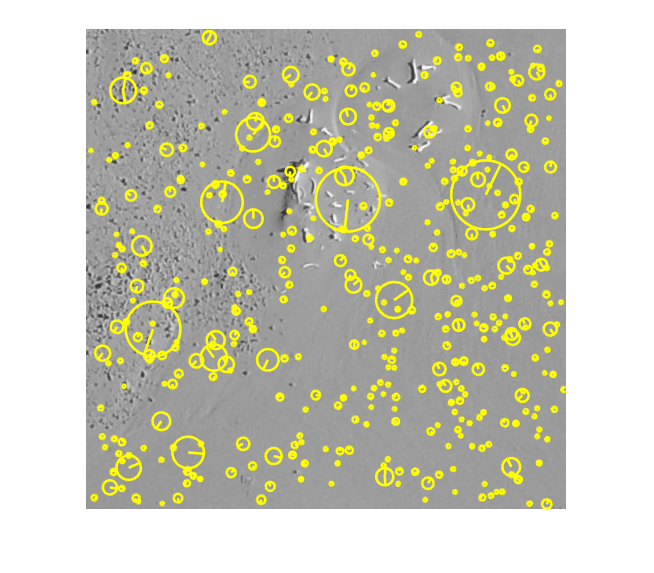

I = imread("Selection_imagettes\Carcasse\237_29.png");
I = single(rgb2gray(I)) ;

edge_thresh = 10;
peak_thresh = 0;
edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;
figure,imshow(I/255) ;
h2 = vl_plotframe(edgePoints) ;
set(h2,'color','y','linewidth',2) ;

Il y a trop de faux positifs, on décide d'optimiser les paramètres.

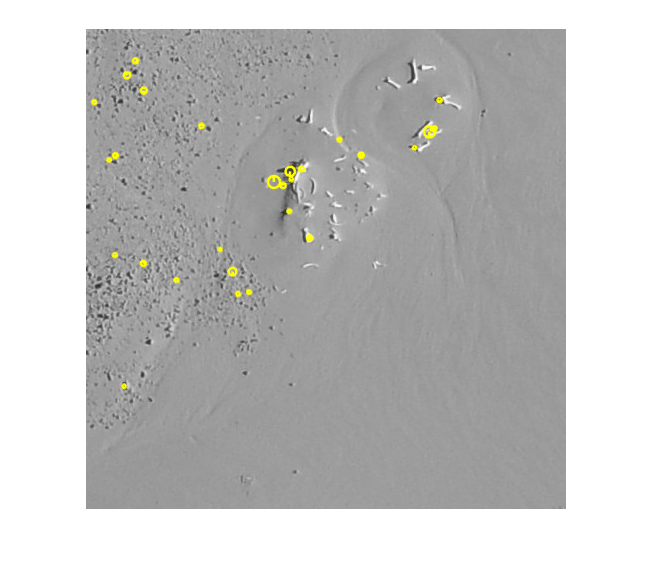

edge_thresh = 10;
peak_thresh = 2;
edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;
figure,imshow(I/255) ;
h2 = vl_plotframe(edgePoints) ;
set(h2,'color','y','linewidth',2) ;

Après optimisation, seul les points appartenant à la carcasse sont détectés, à l'exception d'un faux positif en bas à gauche.

SIFT semble mieux fonctionner pour détecter  les carcasses que les barrières de barbelés.

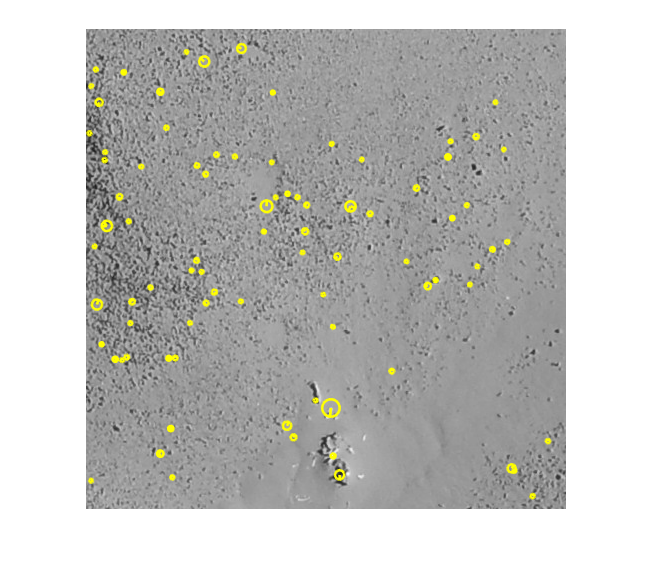

I = imread("Selection_imagettes\Carcasse\247_28.png");
I = single(rgb2gray(I)) ;
edge_thresh = 10;
peak_thresh = 2;
edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;
figure,imshow(I/255) ;
h2 = vl_plotframe(edgePoints) ;
set(h2,'color','y','linewidth',2) ;

En essayant la méthode sur une image plus bruitée, les résultats ne sont pas aussi bon. Pour cette image en particulier, on peut augmenter le peak treshold, mais si il est trop élevé, les carcasses ne sont plus détectées sur d'autres images. Il faut développer une nouvelle approche pour se débarasser des faux positifs.

## Blanchiment des points saillants

On choisit de ne conserver que les points dont le voisinage contient un point suffisamment blanc. En effet, après observation, il s'avère que les carcasses sont les éléments les plus blancs des imagettes.

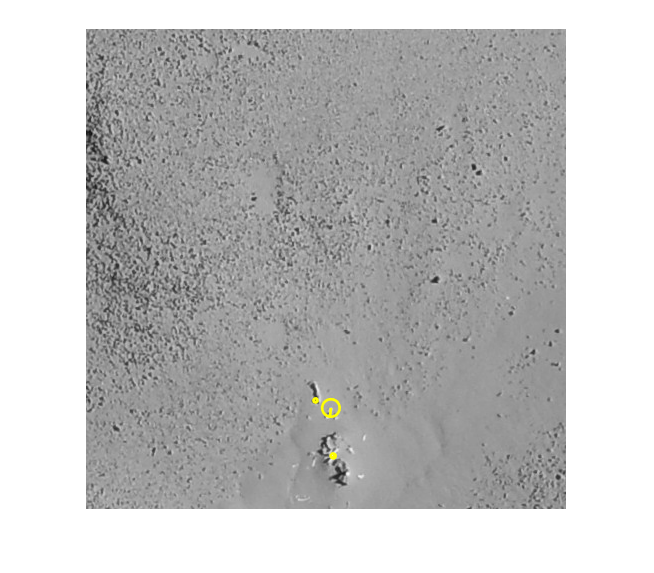

edge_thresh = 10;
peak_thresh = 2;
edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh);

whiteThreshold=207;
neighbourhoodSize=5;
whitestPoints=keepWhiteEdgePoints(I,edgePoints,whiteThreshold,neighbourhoodSize);

figure,imshow(I/255) ;
if ~ isempty(whitestPoints)

    h2 = vl_plotframe(whitestPoints) ;
    set(h2,'color','y','linewidth',2) ;

end

Les résultats sont meilleurs, on ne détecte que les points qui constitue la carcasse. En testant sur l'ensemble des imagettes contenant une carcasse, les résultats semblent satisfaisants.

## Amélioration de la méthode avec les n-voisins

La méthode développée précédemment détecte bien les carcasses et permet d'éviter un certain nombre de faux positifs, mais certains faux positifs ne sont pas éliminés dans le processus. Un des exemple courant est une imagette contenant des cailloux blancs. Ces caillous constistuent des points saillants car ils contrastent avec le fond de l'imagette. COmme ces caillous sont blancs ils ne sont pas éliminés par le blanchiment.

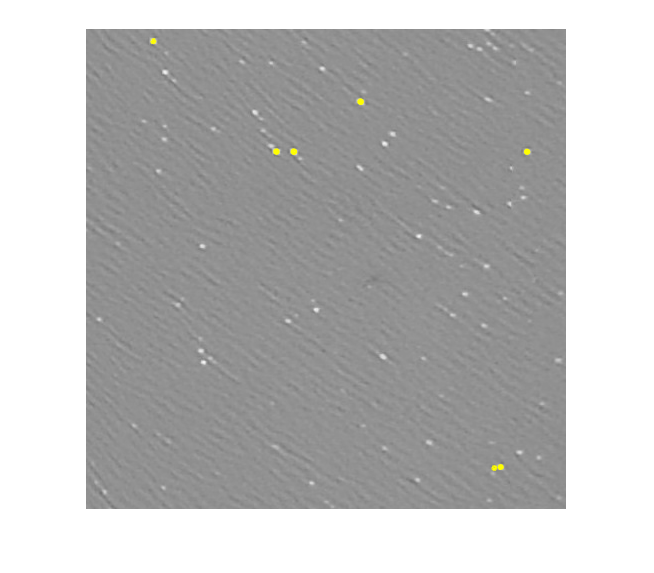

I = imread("imagettes/161_70.png");
I = single(rgb2gray(I)) ;
edge_thresh = 10;
peak_thresh = 4;
edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh);

whiteThreshold=207;
neighbourhoodSize=5;
whitestPoints=keepWhiteEdgePoints(I,edgePoints,whiteThreshold,neighbourhoodSize);
figure,imshow(I/255) ;
if ~ isempty(whitestPoints)

    h2 = vl_plotframe(whitestPoints) ;
    set(h2,'color','y','linewidth',2) ;

end

On décide donc d'améliorer la méthode précédente en rajoutant une étape dans l'algorithme. On ne conserve que les points blancs qui ont dans leur voisinage proche d'autres points saillants blancs. De cette manière, on ne conserve pas les images de petits cailloux blancs qui contiennent pleins de points blancs dispersés dans l'image.

On décide que pour être conservé un point doit avoir au moins 4 voisins dans un voisinage d'un mètre (taille approximative d'une carcasse).

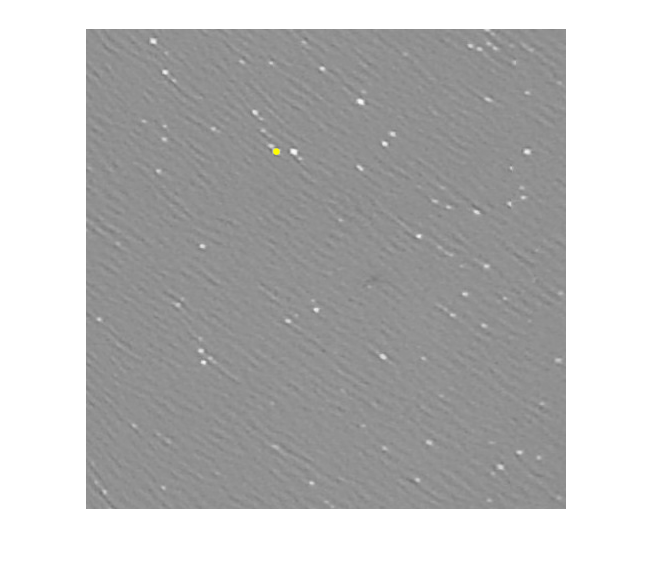

edge_thresh = 10;
peak_thresh = 2;
whiteThreshold = 207;
neighbourhoodSize= 15;    
distanceTreshold =40; %= 1meters
nNeighboors=4;   

points = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;    

whitestPoints=keepWhiteEdgePoints(I,points,whiteThreshold,neighbourhoodSize);

closestPoints=keepCloseEdgePoints(whitestPoints,distanceTreshold,nNeighboors);

if ~ isempty(closestPoints)
    figure,imshow(I/255) ;
    h2 = vl_plotframe(closestPoints) ;
    set(h2,'color','y','linewidth',2) ;
end

On voit que ce traitement a efficacement supprimé les faux positifs. Il ne reste plus qu'un seul point saillant blanc. En rajoutant un critère de sélection, on ne conserve que les imagettes qui ont a minima 4 points saillants blancs qui ont 4 voisins dans un périmètre d'un mètre.

## Métriques

Nous allons maintenant comparer les résultats avec ces différentes méthodes appliquées à l'ensemble des imagettes

directoryPath='Selection_imagettes/Carcasse';
files=dir(directoryPath);
%drop '.' and '..' paths
files=files(3:end);
Reality=[];
for p = 1:numel(files)
    Reality=[Reality, string(files(p).name)];
end

directoryPath='imagettes';

files=dir(directoryPath);

%drop '.' and '..' paths
files=files(3:end);

nbImagettes=size(files,1);

tic
carcassSWIFTPrediction=[];
for p = 1:numel(files)
    fullpath= append(directoryPath,'/',files(p).name);
    
    I = imread(fullpath);
    I = single(rgb2gray(I)) ;
    
    edge_thresh = 10;
    peak_thresh = 2;
    edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh);
        
    if size(edgePoints,2)>3
        carcassSWIFTPrediction=[carcassSWIFTPrediction, string(files(p).name)];    
    end
   
end  
toc

Elapsed time is 515.677143 seconds.


tic
carcassWhitePrediction=[];
for p = 1:numel(files)
    fullpath= append(directoryPath,'/',files(p).name);
    
    I = imread(fullpath);
    I = single(rgb2gray(I)) ;
    
    edge_thresh = 10;
    peak_thresh = 2;
    edgePoints = vl_sift(I, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh);
    
    whiteThreshold=207;
    neighbourhoodSize=15;
    whitestPoints=keepWhiteEdgePoints(I,edgePoints,whiteThreshold,neighbourhoodSize);
    
    if size(whitestPoints,2)>3
        carcassWhitePrediction=[carcassWhitePrediction, string(files(p).name)];    
    end
   
end  
toc

Elapsed time is 514.300246 seconds.


tic
carcassPrediction=[];
for p = 1:numel(files)
    fullpath= append(directoryPath,'/',files(p).name);
    
    I = imread(fullpath);
    I = single(rgb2gray(I)) ;    
    
    if detectCarcass(I)
        carcassPrediction=[carcassPrediction, string(files(p).name)];    
    end
   
end 
toc

Elapsed time is 531.512671 seconds.


getMetrique(carcassSWIFTPrediction,Reality,nbImagettes)

true_positive = 75

false_positive = 13404

false_negative = 0

true_negative = 1064

Accuracy = 0.0783

Sensibility = 1

Specificity = 0.0735

getMetrique(carcassWhitePrediction,Reality,nbImagettes)

true_positive = 51

false_positive = 1275

false_negative = 24

true_negative = 13193

Accuracy = 0.9107

Sensibility = 0.6800

Specificity = 0.9119

getMetrique(carcassPrediction,Reality,nbImagettes)

true_positive = 44

false_positive = 738

false_negative = 31

true_negative = 13730

Accuracy = 0.9471

Sensibility = 0.5867

Specificity = 0.9490

Les résultats sont assez bons, si on prend en comtpe la rareté des carcasses dans l'image. Il faut nuancer le nombre de faux négatifs par le fait qu'un certain nombre d'imagette classifié à la main comme contenant une carcasse sont mal classées. Il s'agit parfois de cailloux ressemblant à des carcasses par exemple. Avec une vérification de la classification à la main. On conclut que le meilleur algorithme pour détecter les carcasses combine sift, le blanchiment et la sélection par voisinage. Il y a un type d'image de carcasse qui est mal appréhender par notre méthode, c'est le cas d'un os seul, trop petit pour contenir plusieuurs points saillants.

function result=keepCloseEdgePoints(Points,distanceTreshold,nNeighboors)

    % The idea is to keep only the edges points which have at least nNeighboors  
    %( neighboor points need to have be closest to the distanceTreshold)
    
    nPoints=size(Points,2);
    wantedPoints=[];
    for point=1:nPoints   
        neighboors = 0;
        for otherpoint=1:nPoints          
          if pdist2([Points(1,point) Points(2,point)], [Points(1,otherpoint) Points(2,otherpoint)]) < distanceTreshold 
            neighboors=neighboors+1 ;
          end          
          if neighboors > nNeighboors
              wantedPoints=[wantedPoints,Points(:,point)];
              break
          end
          
        end    
    end   
      
    result=wantedPoints;

end    


function result=keepWhiteEdgePoints(Imagette,Points,whiteThreshold,neighbourhoodSize)
    
    nPoints=size(Points,2);
    
    % The idea is to keep only the whiter edges points
    ImagetteSize=size(Imagette,1);
    wantedPoints=[];
    for point=1:nPoints
      x=round(Points(1,point));
      y=round(Points(2,point));
      startCol=max(x-neighbourhoodSize,1);
      endCol=min(x+neighbourhoodSize,ImagetteSize);
      startRow=max(y-neighbourhoodSize,1);
      endRow= min(y+neighbourhoodSize,ImagetteSize);
      for col=startCol:endCol
        for row=startRow:endRow 
            if Imagette(row,col)>whiteThreshold
              wantedPoints=[wantedPoints,Points(:,point)];
              break
            end
        end
            if Imagette(row,col)>whiteThreshold
              break
            end
      end
          
    end   
      
    result=wantedPoints;

end 

function result=detectCarcass(Imagette)
    
    result=0;
    edge_thresh = 10;
    peak_thresh = 2;
    whiteThreshold = 207;
    neighbourhoodSize= 15;    
    distanceTreshold =40; %= 1meters
    nNeighboors=4;   
    
    points = vl_sift(Imagette, 'PeakThresh', peak_thresh, 'edgethresh', edge_thresh) ;    

    whitestPoints=keepWhiteEdgePoints(Imagette,points,whiteThreshold,neighbourhoodSize);

    closestPoints=keepCloseEdgePoints(whitestPoints,distanceTreshold,nNeighboors);
    
    if size(closestPoints,2)>3
%         figure,imshow(Imagette/255) ;
%         h2 = vl_plotframe(closestPoints) ;
%         set(h2,'color','y','linewidth',2) ;
        result=1;
    end
end

function getMetrique(prediction,reality,nbImagettes)


    %Calculs des vrai/faux positifs et négatifs
    true_positive=length(intersect(reality,prediction))
    
    false_positive=length(prediction)-true_positive
    
    false_negative = length(reality)-true_positive
    
    true_negative = nbImagettes - true_positive - false_positive - false_negative
    
    
    %Le premier métrique assez représentatif de la performance est la "probabilité à priori" correspondant à la probabilité d'obtenir un résultat correct (positif et négatif) parmi l'ensemble des résultats.
    %%% probabilité à priori %%%
   Accuracy = (true_positive+true_negative)/(true_positive+true_negative+false_negative+false_positive)
    % Pour bien évaluer la performance, il est nécessaire de calculer la sensibilité et la spécificité du test.
    % La sensibilité correspond à la probabilité d'obtenir un résultat positif correct. La spécificité correspond à la probabilité d'obtenir un résultat négatif correct.
    %%% sensibilité %%%
    Sensibility = true_positive/(true_positive+false_negative)
    %%% spécificité %%%
    Specificity = true_negative/(true_negative+false_positive)
end    